## ***Kdoms Term Project:***

***Animation Code:***

Storing initial values:

r1 = 15;
r2 = 5;
r3 = 18.045;
r4 = 6.087;
theta_1 = 0;

**Note:** We took r2 as rocker and r4 as crank, different from usual notation.

Now, the animation code:

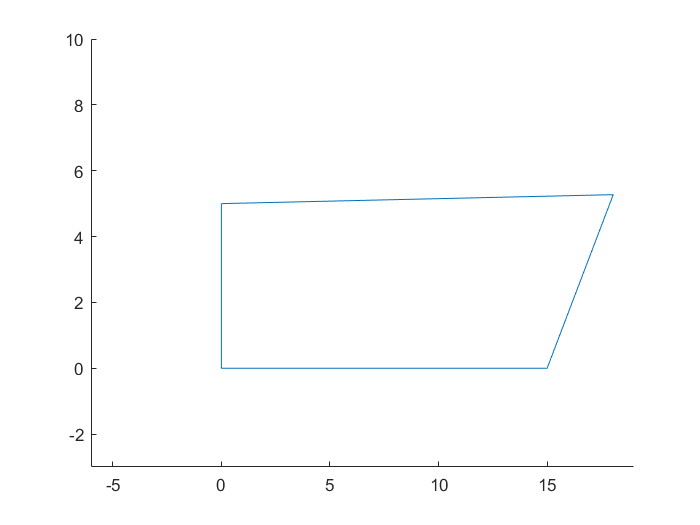

settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;
figure;
for theta_2 = pi/2 : (1/120)*pi : 7*pi/6
theta_4 = t4(r1,r2,r3,r4,theta_1,theta_2);
theta_3 = t3(r1,r2,r4,theta_1,theta_2,theta_4);
plotPos(r1,r2,r4,theta_1,theta_2,theta_4);
%drawnow;
pause(0.05)
clf
end
for theta_2 = 7*pi/6 : -(1/120)*pi : pi/2
theta_4 = t4(r1,r2,r3,r4,theta_1,theta_2);
theta_3 = t3(r1,r2,r4,theta_1,theta_2,theta_4);
plotPos(r1,r2,r4,theta_1,theta_2,theta_4);
%drawnow;
pause(0.05)
clf
end
plotPos(r1,r2,r4,theta_1,theta_2,theta_4);

Function to find theta_4 if theta_2 is known:

function theta_4 = t4(r1,r2,r3,r4,theta_1,theta_2)
  A= 2*r1*r4*cos(theta_1)-2*r2*r3*cos(theta_2);
  B= 2*r1*r4*sin(theta_1)-2*r2*r4*sin(theta_2);
  C= r1^2 + r2^2 + r4^2 -r3^2 - 2*r1*r2*cos(theta_2 - theta_1);
  theta_4 = 2*(atan((-B-sqrt(B^2 + A^2 - C^2))/(C-A)));
end

**Note: **We used only one solution of theta_4 because, that solution gives our required linkage.

Function to find theta_3 if theta_4 and theta_2 are known:

function tita3 = t3(r1,r2,r4,theta_1,theta_2,theta_4)
 tita3= atan((r1*sin(theta_1) + r4*sin(theta_4) - r2*sin(theta_2))/(r1*cos(theta_1)+r4*cos(theta_4)-r2*cos(theta_2)));
end

Function to plot required Position after position analysis is complete.

function [] = plotPos(r1,r2,r4,theta_1,theta_2,theta_4)
      p1 = [0 0];
      p2 = [r1*cos(theta_1) r1*sin(theta_1)];
      p3 = [(r1 + r4*cos(theta_4)) (r4*sin(theta_4))];
      p4 = [r2*cos(theta_2) r2*sin(theta_2)];
      hold on
      plot([p1(1) p2(1) p3(1) p4(1) p1(1)],[p1(2) p2(2) p3(2) p4(2) p1(2)])
      xlim([-6,19])
      ylim([-3,10])
end